# INME 4012 - Project

# Machine Design

## Scenario: 

A punch press is used to stamp circular steel washers from a workpiece. A schematic of the washer producing device is shown below. A flywheel is directly coupled to a crankshaft. An electric motor drives the crankshaft via a gear reducer. As the motor rotates, a punching die reciprocates producing washers each revolution of the crankshaft. The purpose of the flywheel is to reduce the size of the motor and gearbox necessary to produce these washers. The optimal motor speed is 1000-1,100 RPM. The crankshaft diameter is 55 mm and fabricated from ASTM 1018 annealed steel. In order to meet production demands, 100 disks are produced each minute. The crankshaft torque necessary to stamp each washer is shown in a separate figure below. During “punching”, the flywheel speed is reduced and the energy to reduce the flywheel speed is used to “help” produce the washers. The motor increases the speed of the flywheel during the non-punching region. Also shown below is the flywheel speed variation. 

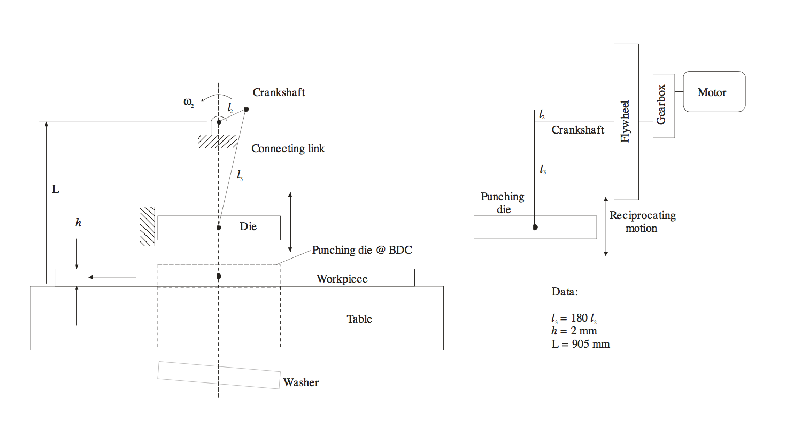

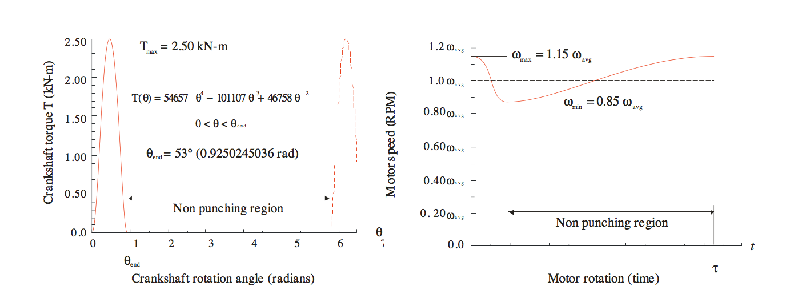

The following information is given:

crankshaftDiameter = 55; % mm
l2 = crankshaftDiameter;
h = 2; % mm
l3 = 180*l2;
L = 905; % mm

The torque can be computed as:

thetaEnd = 53; %deg
fracPress = round(10000*(thetaEnd/360));
fracNoPress = round(10000*((360-thetaEnd)/360));
thetaPress = linspace(0,0.9250245036,fracPress);
torqueEq = @(thetaVar) 54657.*(thetaVar.^4)-101107*(thetaVar.^3)+46758*(thetaVar.^2);
torquePress = torqueEq(thetaPress);
SecondPress = 360-0.5*thetaEnd;
SecondPress = SecondPress*(pi/180);
thetaNoPress = linspace(0.9250245036,SecondPress,fracNoPress+1);
thetaPress2 = linspace(SecondPress,SecondPress+0.9250245036,fracPress);
thetaNoPress2 = linspace(SecondPress+0.9250245036,2*SecondPress,fracNoPress+1);
thetaPress3 = linspace(2*SecondPress,2*SecondPress+0.9250245036,fracPress);
thetaNoPress3 = linspace(2*SecondPress+0.9250245036,3*SecondPress,fracNoPress+1);
thetaPress4 = linspace(3*SecondPress,3*SecondPress+0.9250245036,fracPress);
thetaNoPress4 = linspace(3*SecondPress+0.9250245036,4*SecondPress,fracNoPress+1);
thetaPress5 = linspace(4*SecondPress,4*SecondPress+0.9250245036,fracPress);
thetaNoPress5 = linspace(4*SecondPress+0.9250245036,5*SecondPress,fracNoPress+1);
thetaPress6 = linspace(5*SecondPress,5*SecondPress+0.9250245036,fracPress);

The torque behaves as:

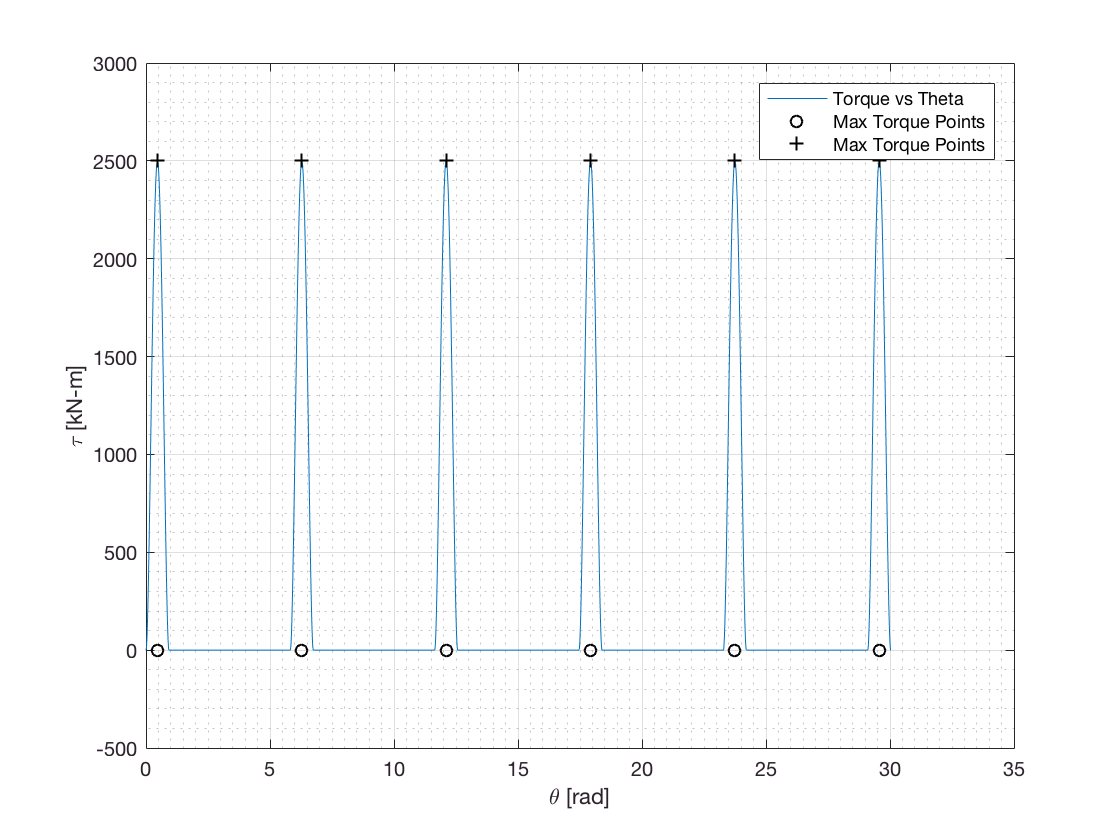

theta = [thetaPress,thetaNoPress,thetaPress2,thetaNoPress2,...
    thetaPress3,thetaNoPress3,thetaPress4,thetaNoPress4,thetaPress5,thetaNoPress5,thetaPress6];
torque = [torquePress,zeros(1,numel(thetaNoPress)),torquePress,...
    zeros(1,numel(thetaNoPress2)),torquePress,zeros(1,numel(thetaNoPress3)),...
    torquePress,zeros(1,numel(thetaNoPress2)),torquePress,zeros(1,numel(thetaNoPress2)),torquePress];
figure('Name','Torque vs Theta')
plot(theta,torque); hold on

scatter([(0.5*0.9250245036),2*pi,4*pi-(0.5*0.9250245036),...
    6*pi-2*(0.5*0.9250245036),8*pi-3*(0.5*0.9250245036),...
    10*pi-4*(0.5*0.9250245036)],[0,0,0,0,0,0],'ko')
scatter([(0.5*0.9250245036),2*pi,4*pi-(0.5*0.9250245036),...
    6*pi-2*(0.5*0.9250245036),8*pi-3*(0.5*0.9250245036),...
    10*pi-4*(0.5*0.9250245036)],[2500,2500,2500,2500,2500,2500],'k+')

legend('Torque vs Theta','Max Torque Points','Max Torque Points')
xlabel('\theta [rad]')
ylabel('\tau [kN-m]')
grid on
grid minor

Attempting to determine the punch press' speed, we determine how many radians are required per spike. From this estimate, whose accuracy will increase with more spikes as a cummulative error exists. From the problem statement, we know that 100 disks are required per minute. 

The central point of any spike beyond the third spike can be determined using the following equation:


$$T_{max_{location}}=2(n-1)\pi-(n-2)(\frac{53\pi}{360})$$


The rightmost point can be easily determined by adjusting the second term in the previous equation:


$$T_{max_{location}}=2\pi (n-1)-(n-1)(\frac{53\pi}{360})\\
T_{max_{location}}=(2\pi - (\frac{53\pi}{360}))(n-1)\\
T_{max_{location}} \approx 5.8207(n-1)$$


From this equation we determine the 100th spike location to be:

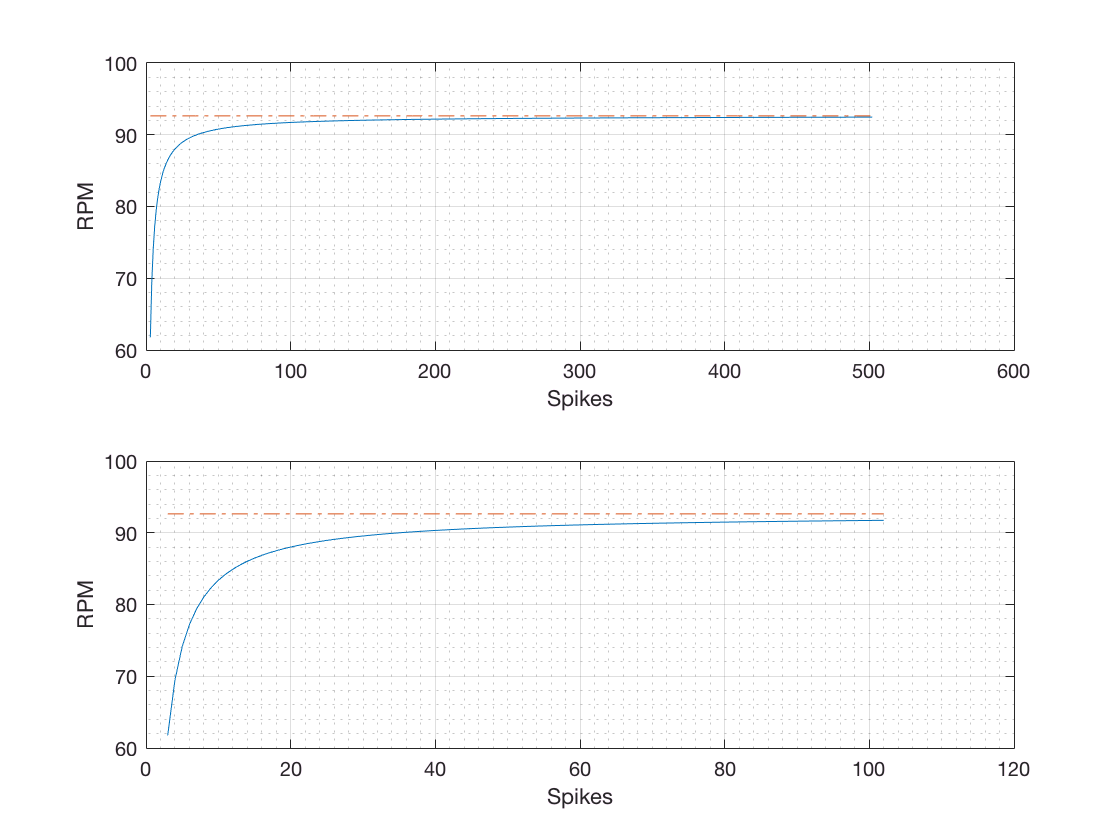

spikes = [3:1000000];
% Here, the full expression is used to facilitate code maintenance.
EstimatedRadians = (2.*(spikes-1).*pi)-((spikes-1).*(0.5*0.9250245036));
EstimatedRevs = EstimatedRadians./(2*pi); % revs
RevsPerSpike = EstimatedRevs./spikes; % revs/spikes
ReqDisks = 100;
RequiredRPMs = RevsPerSpike.*ReqDisks;
figure('Name','EstimatedRevs vs Terms Used')
subplot(2,1,1)
plot(spikes(1:500),RequiredRPMs(1:500)); hold on
plot(spikes(1:500),max(RequiredRPMs).*ones(1,numel(spikes(1:500))),'-.')
xlabel('Spikes')
ylabel('RPM')
grid on 
grid minor
subplot(2,1,2)
plot(spikes(1:100),RequiredRPMs(1:100)); hold on
plot(spikes(1:100),max(RequiredRPMs).*ones(1,numel(spikes(1:100))),'-.')
xlabel('Spikes')
ylabel('RPM')
grid on 
grid minor

As seen from the previous figure, the log-like trend tends asymptotically to a certain limit. However, using 100 spikes yields a reasonable approximation. Given the power of modern computing hardware, we will use a 1M spikes for a smooth approximation.

RequiredRPMs = max(RequiredRPMs)

RequiredRPMs = 92.6388

The required RPM for the punch press' motor are much higher than the one required for the actual pressing mechanism.

MotorRPMs = 1020; % Yields a value near integer for the reduction
GearboxReduction = round(MotorRPMs/RequiredRPMs)

GearboxReduction = 11

Three reductions will be used:

**First Reduction -> 1:2**

**Second Reduction -> 1:2**

**Third Reduction -> 1:2.75 **

**Overall GearBox Reduction -> 1:11**

GearNo = 6;
FirstReduction = 2;
SecondReduction = 2;
ThirdReduction = 2.75;

## Building the gearbox

The proposed gearbox has 3 gear pairs. The governing equations are:


$$\frac{N_2}{N_1}=2\\

\frac{N_4}{N_3}=2\\

\frac{N_6}{N_5}=2.75\\ \\

N_1+N_2=N_3+N_4\\
N_3+N_4=N_5+N_6\\
N_1+N_2=N_5+N_6$$


From these equations and some algebraic manipulation,


$${N_2}=2{N_1}\\

{N_4}=2{N_3}\\

{N_6}=2.75{N_5}\\ \\

{N_1}={N_3}\\
{N_3}=1.25{N_5}\\$$


We'll leave these expressions momentarily and move to compute the maximum and minimum angular speeds according to the problem statement. Further, we will compute the required energy (ie work)